# Generate Alternative Trajectories for Reference Path

Generate alternative trajectories for a reference path using Frenet coordinates. Specify different initial and terminal states for your trajectories. Tune your states based on the generated trajectories.

Generate a reference path from a set of waypoints. Create a `trajectoryGeneratorFrenet` object from the reference path.

%waypoints = [0 0; ...
%	50 20; ...
%	100 0; ...
%	150 10];
waypoints = [path.VarName1 path.VarName2];



x_wp = path.VarName1;
y_wp = path.VarName2;

QP_x = [];
QP_y = [];

for i =1:length(x_wp)-1
    A = [x_wp(i),y_wp(i)];
    B = [x_wp(i+1),y_wp(i+1)];
    N= 50;
    x = [A(1) B(1)];
    y = [A(2) B(2)];
    qp_x = linspace(x(1),x(2),N+2);
    qp_y = linspace(y(1),y(2),N+2);
    qp_x(end)=[];
    qp_x(1)=[];
    QP_x = [QP_x,qp_x];
    qp_y(end)=[];
    qp_y(1)=[];
    QP_y = [QP_y,qp_y];
end


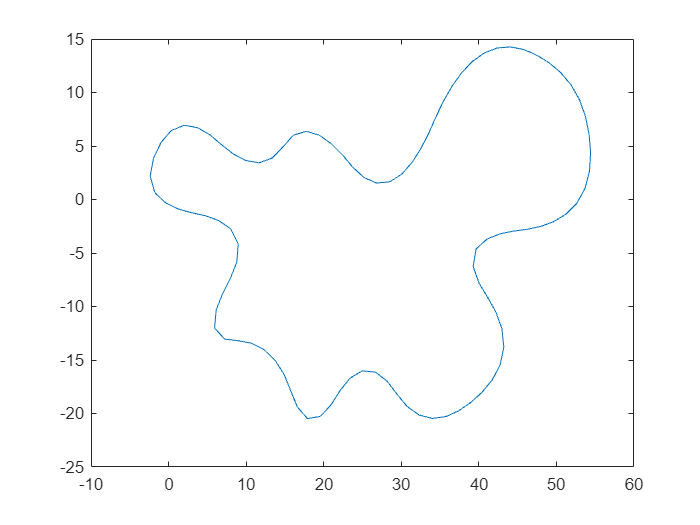

figure
plot(QP_x,QP_y)

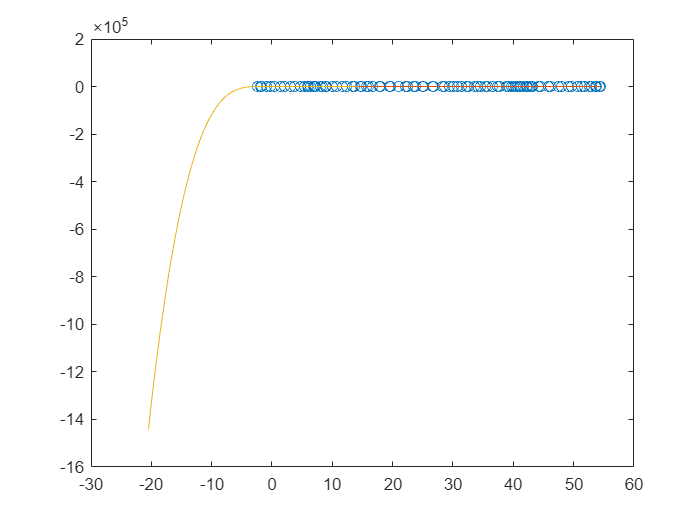

base_path = [QP_x;QP_y];

figure
xx = [QP_x(:) QP_y(:)];
yy = spline(x_wp,y_wp,xx);
plot(x_wp,y_wp,'o',xx,yy)

%ArcPath = [refPath.SegmentParameters(:,1),refPath.SegmentParameters(:,2),refPath.SegmentParameters(:,6)];


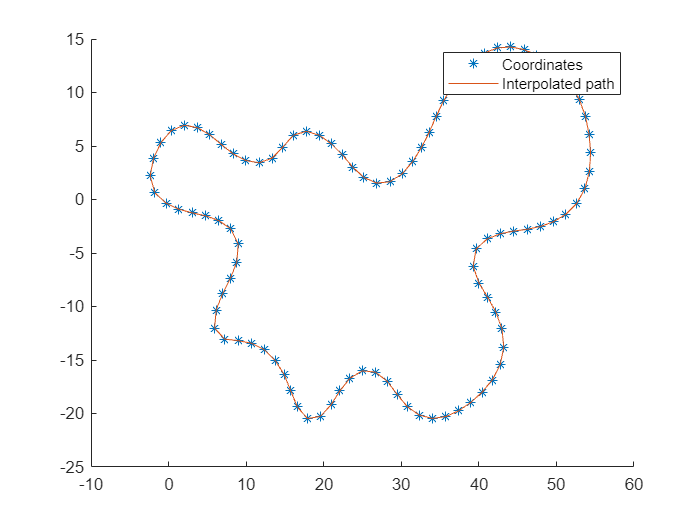



refPath = referencePathFrenet([QP_x' QP_y']);

figure
hold on
plot(path.VarName1,path.VarName2,'*')
plot(refPath.SegmentParameters(:,1),refPath.SegmentParameters(:,2))
hold off
legend('Coordinates','Interpolated path')

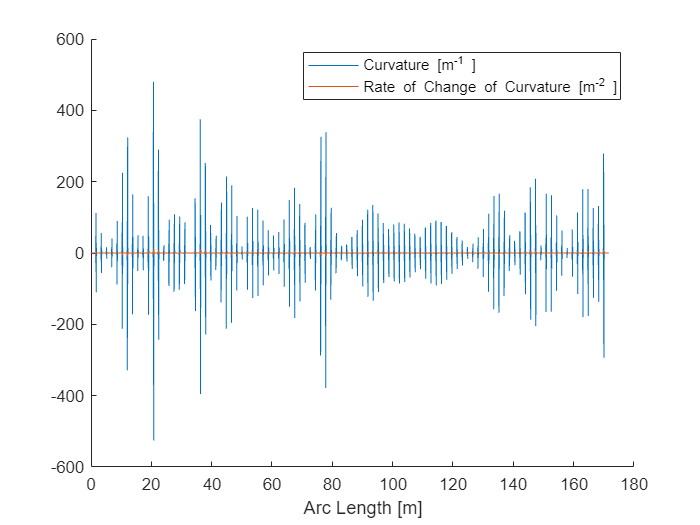



figure
hold on
plot(refPath.SegmentParameters(:,6),refPath.SegmentParameters(:,5))
plot(refPath.SegmentParameters(:,6),refPath.SegmentParameters(:,4))
hold off
legend('Curvature [m^-1 ]','Rate of Change of Curvature [m^-2 ]')
xlabel('Arc Length [m]')

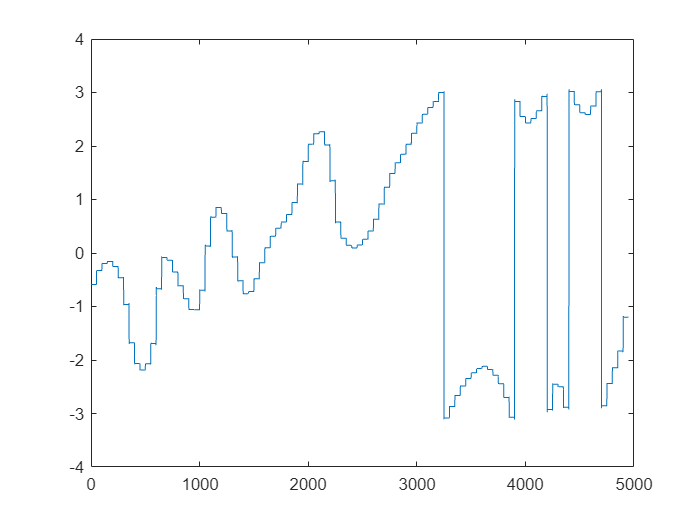

figure
plot(refPath.SegmentParameters(:,3))

quat = eul2quat([refPath.SegmentParameters(:,3),zeros(length(refPath.SegmentParameters(:,3)),1),zeros(length(refPath.SegmentParameters(:,3)),1)]);
ArcPath = [refPath.SegmentParameters(:,1),refPath.SegmentParameters(:,2),refPath.SegmentParameters(:,3),quat(:,1),quat(:,2),quat(:,3),quat(:,4),refPath.SegmentParameters(:,4),refPath.SegmentParameters(:,5),refPath.SegmentParameters(:,6)];


connector = trajectoryGeneratorFrenet(refPath);

Generate a five-second trajectory between the path origin and a point 30 m down the path as Frenet states.

initState = [0 0 0 0 0 0];  % [S ds ddS L dL ddL]
termState = [15 0 0 0 0 0]; % [S ds ddS L dL ddL]
[~,trajGlobal] = connect(connector,initState,termState,5);

Display the trajectory in global coordinates.

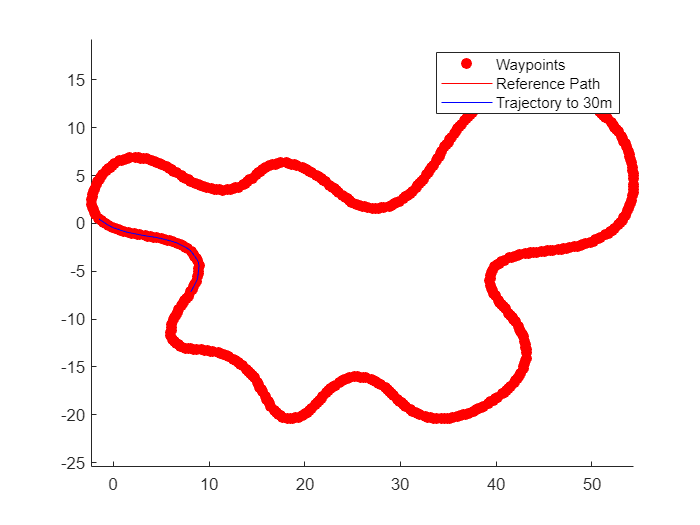

show(refPath);
hold on
axis equal
plot(trajGlobal.Trajectory(:,1),trajGlobal.Trajectory(:,2),'b')
legend(["Waypoints","Reference Path","Trajectory to 30m"])

Create a matrix of terminal states with lateral deviations between –3 m and 3 m. Generate trajectories that cover the same arc length in 10 seconds, but deviate laterally from the reference path. Display the new alternative paths.

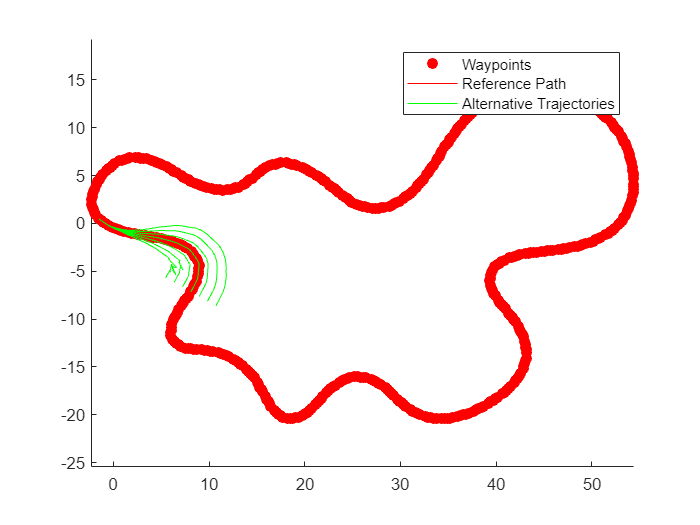

termStateDeviated = termState + ([-3:3]' * [0 0 0 1 0 0]);
[~,trajGlobal] = connect(connector,initState,termStateDeviated,10);

clf
show(refPath);
hold on
axis equal
for i = 1:length(trajGlobal)
    plot(trajGlobal(i).Trajectory(:,1),trajGlobal(i).Trajectory(:,2),'g')
end
legend(["Waypoints","Reference Path","Alternative Trajectories"])
hold off

Specify a new terminal state to generate a new trajectory. This trajectory is not desirable because it requires reverse motion to achieve a longitudinal velocity of 10 m/s.

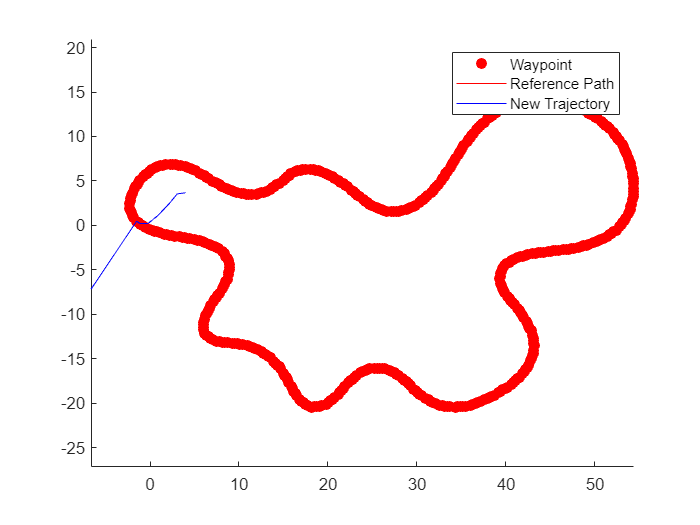

newTermState = [5 10 0 5 0 0];
[~,newTrajGlobal] = connect(connector,initState,newTermState,3);

clf
show(refPath);
hold on
axis equal
plot(newTrajGlobal.Trajectory(:,1),newTrajGlobal.Trajectory(:,2),'b');
legend(["Waypoint","Reference Path","New Trajectory"])
hold off

Relax the restriction on the longitudinal state by specifying an arc length of `NaN`. Generate and display the trajectory again. The new position shows a good alternative trajectory that deviates off the reference path.

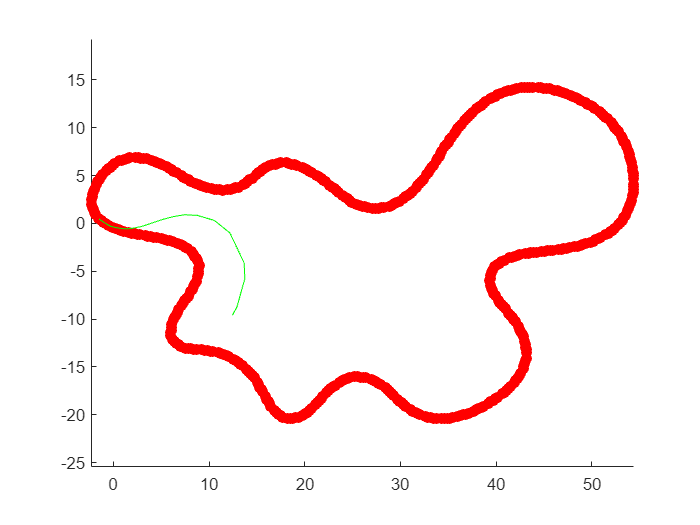

relaxedTermState = [NaN 10 0 5 0 0];
[~,trajGlobalRelaxed] = connect(connector,initState,relaxedTermState,3);

clf
show(refPath);
hold on
axis equal
plot(trajGlobalRelaxed.Trajectory(:,1),trajGlobalRelaxed.Trajectory(:,2),'g');
hold off

*Copyright 2020 The MathWorks, Inc.*